# KUKA6

Simulation of a KUKA 6DOF with motion planning.

### **Startup**

% Startup configuration
config.space = 2;
config.trajectory = 3;
startup;

Reload D-H parameters...
Reload Dynamic parameters...
Creating SixAxesRobot...
Kuka 6-DOF: "SixAxesRobot"
-------------------------------------
DH Parameters: 
     d       a      alpha     offset
    ____    ___    _______    ______

     335     75    -1.5708      0   
       0    270          0      0   
       0     90     1.5708      0   
    -295      0    -1.5708      0   
       0      0     1.5708      0   
     -80      0     3.1416      0   

Masses: 
   26.9797
   15.9204
   25.8524
    4.0885
    1.6154
    0.0160

Reload Waypoints from "loadWaypointQuadrilater3"...
numel(waypoints) =
     5

Reload Bus Objects...
Opening model "KukaSimModel.slx"...
Setting "StopTime"=20s...
Setting Variant TP_MODE=2->["JointSpace"]
Initialization Done.



taskColor = [.64 .02 .03];
jointColor = [.02 .52 .51];

### **Simulate TaskSpace**

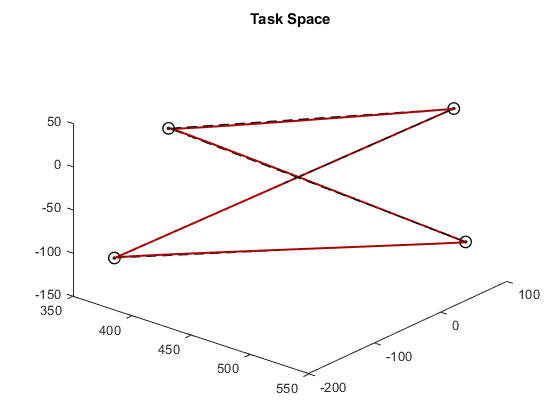

TP_MODE = 1; %#ok<NASGU> - set Variant Subsystem
simOutTask = sim('KukaSimModel');

figure; hold on;
plotWaypoints(waypointsStruct);

% plot trajectory
pos_taskSpace = simOutTask.logsout.getElement('pos_taskSpace').Values;
values = reshape(pos_taskSpace.Data(:, 6, 1:end-1), 3, numel(simOutTask.tout)-1);
plot3(values(1, :), ...
    values(2, :), ...
    values(3, :), ...
    "Color", taskColor, "LineWidth", 1.5);
title('Task Space');
view(40,35);

### **Simulate JointSpace**

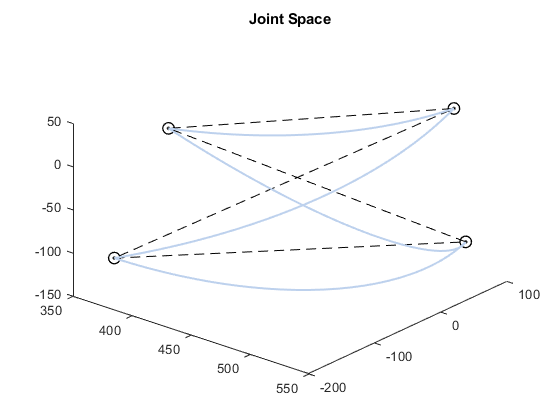

TP_MODE = 2; % set Variant Subsystem
simOutJoint = sim('KukaSimModel');

figure; hold on;
plotWaypoints(waypointsStruct);

% plot trajectory
pos_jointSpace = simOutJoint.logsout.getElement('pos_jointSpace').Values;
values = reshape(pos_jointSpace.Data(:, 6, 1:end-1), 3, numel(simOutJoint.tout)-1);
plot3(values(1, :), ...
    values(2, :), ...
    values(3, :), ...
    "Color", jointColor, "LineWidth", 1.5);
title('Joint Space');
view(40,35);

### Compare q

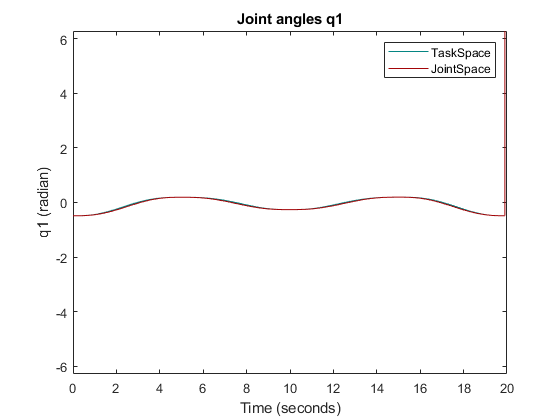

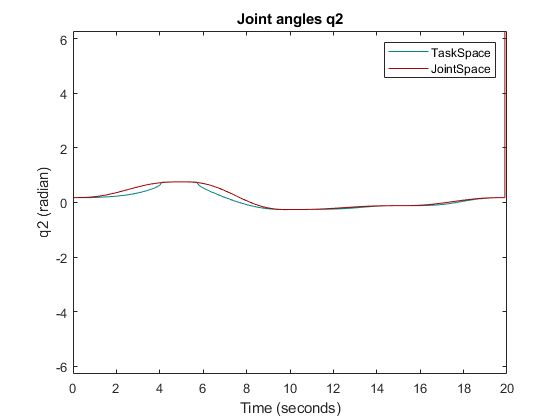

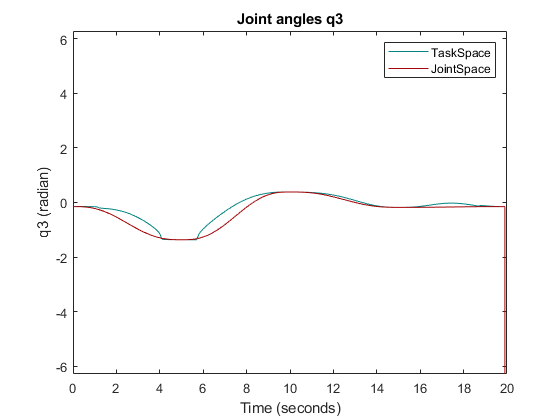

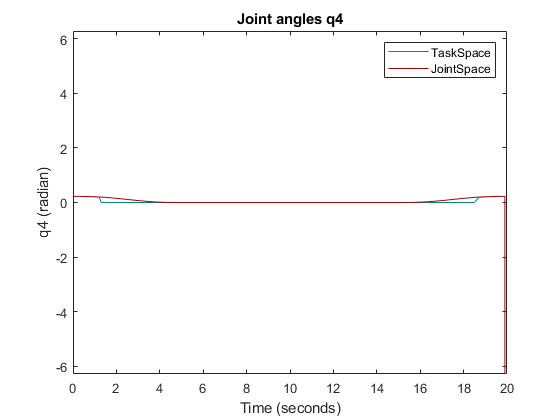

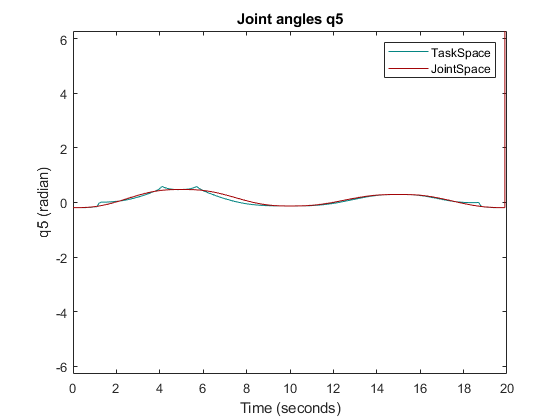

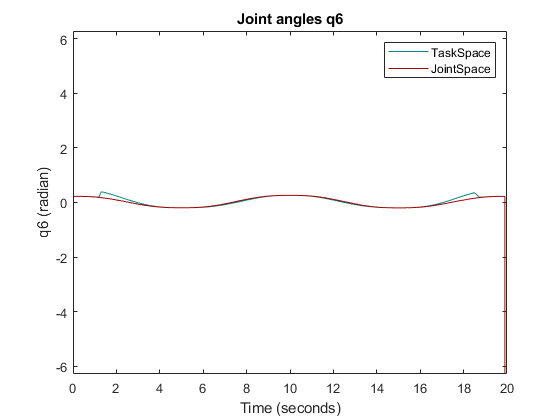

q_taskSpace = simOutTask.logsout.getElement('q_taskSpace').Values;
q_jointSpace = simOutJoint.logsout.getElement('q_jointSpace').Values;
joints = fieldnames(q_taskSpace);
for i=1:numel(joints)
    figure;
    plot(q_taskSpace.(joints{i}), "Color", jointColor); hold on;
    plot(q_jointSpace.(joints{i}), "Color", taskColor); 
    ylim([-2*pi, 2*pi]);
    legend('TaskSpace', 'JointSpace');
    title(sprintf('Joint angles %s', joints{i}));
end

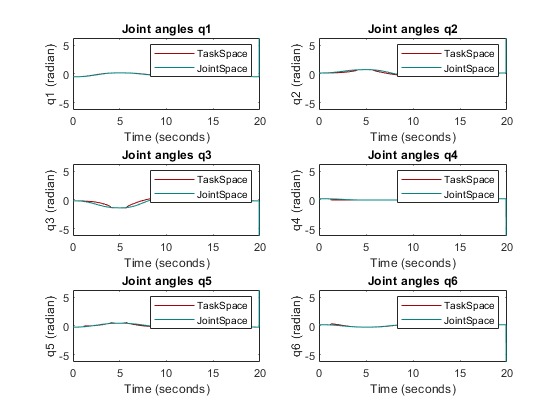


verticalAling = false;
figure; hold on;
for i=1:numel(joints)
    if verticalAling
        align = subplot(6, 1, i);
    else
        align = subplot(3, 2, i);
    end
    plot(q_taskSpace.(joints{i}), "Color", taskColor); hold on;
    plot(q_jointSpace.(joints{i}), "Color", jointColor); 
    ylim([-2*pi, 2*pi]);
    legend('TaskSpace', 'JointSpace');
    title(sprintf('Joint angles %s', joints{i}));
end

function plotWaypoints(waypointsStruct)
% plot waypoints
scatter3(waypointsStruct.waypoints(1, :), ...
    waypointsStruct.waypoints(2, :), ...
    waypointsStruct.waypoints(3, :), ...
    75, "black", 'LineWidth', 1);
scatter3(waypointsStruct.waypoints(1, :), ...
    waypointsStruct.waypoints(2, :), ...
    waypointsStruct.waypoints(3, :), ...
    '.', "black", 'LineWidth', 1.5);
plot3(waypointsStruct.waypoints(1, :), ...
    waypointsStruct.waypoints(2, :), ...
    waypointsStruct.waypoints(3, :), 'k--');
% plot3(waypointsStruct.waypoints(1, [end 1]), ...
%     waypointsStruct.waypoints(2, [end 1]), ...
%     waypointsStruct.waypoints(3, [end 1]), 'k--');
end